clc,clear
% 数据导入
% 地块面积向量
S = readmatrix("E:\数学建模比赛\CUMCM2024Problems\C题\附件1.xlsx",'Sheet','乡村的现有耕地');
S = S(:,3);
S = [S; S(27:54)];

% 2023年耕种情况
x0 = readmatrix("E:\数学建模比赛\初始值.xlsx");
x0 = x0(2:83,3:end);
x0(isnan(x0)) = 0;

% 售价矩阵
P =  readmatrix("E:\数学建模比赛\自处理数据\预期售价.xlsx");    
P = P(:,3:end);
P(isnan(P)) = 0;
%P = [P P P P P P P];

% 预期销售量矩阵
D = readmatrix("E:\数学建模比赛\自处理数据\预期销售量(1).xlsx");
D = D(:,2:end);
D(isnan(D)) = 0;
%D = [D D D D D D D];

% 预期亩产量
q = readmatrix("E:\数学建模比赛\自处理数据\预期亩产量.xlsx");      
q = q(:,3:end);
q(isnan(q)) = 0;
%q = [q q q q q q q];

% 预期亩成本
C = readmatrix("E:\数学建模比赛\自处理数据\预期每亩成本.xlsx");
C = C(:,3:end);
C(isnan(C)) = 0;

%模拟退火算法

[iterations, R_change,R, x1 ,x2 ,x3 ,x4 ,x5 ,x6 ,x7] = sa_tsp(S, x0, P, D, q, C) 

---------------------------------------------------------------


iterations = 59236

R_change = 	1.0e+07 *

    2.3138    2.3129    2.2275    2.4264    2.3669    2.2247    2.2551    2.3060    2.4389    2.3724    2.2578    2.3200    2.2754    2.3436    2.3441    2.2944    2.3614    2.3314    2.2946    2.2494    2.4182    2.3861    2.2681    2.3901    2.2916    2.3450    2.4595    2.2240    2.3970    2.4430    2.3900    2.5111    2.3793    2.3496    2.3443    2.2818    2.3118    2.3239    2.3381    2.3013    2.2539    2.2929    2.3819    2.3463    2.4218    2.3546    2.3964    2.2702    2.2808    2.3244


R = 4.0411e+07

x1 =      0     0     0     3     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     4     2     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x2 =      0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x3 =      0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x4 =      0     0     0     1     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     2     0     2     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x5 =      0     0     0     0     1     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     3     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x6 =      0     0     0     1     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     2     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     2     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x7 =      0     0     0     0     0     2     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1 

n = [1:iterations]

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


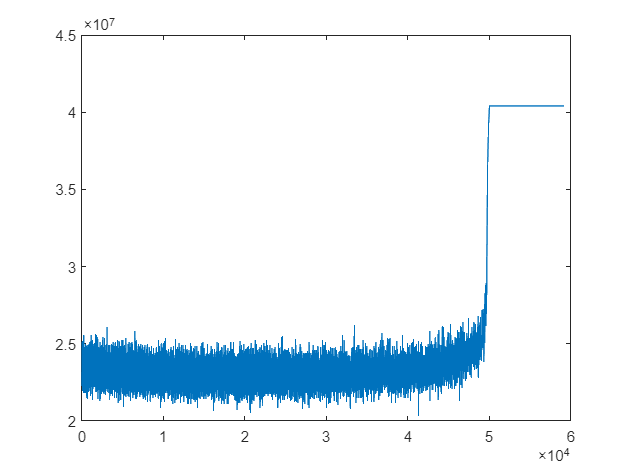

plot(n,R_change,'-')


x1 = x1./sum(x1,2);
x1 = x1.*S;
x1(isnan(x1)) = 0;
writematrix(x1, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2024');

x2 = x2./sum(x2,2);
x2 = x2.*S;
x2(isnan(x2)) = 0;
writematrix(x2, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2025');

x3 = x3./sum(x3,2);
x3 = x3.*S;
x3(isnan(x3)) = 0;
writematrix(x3, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2026');

x4 = x4./sum(x4,2);
x4 = x4.*S;
x4(isnan(x4)) = 0;
writematrix(x4, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2027');

x5 = x5./sum(x5,2);
x5 = x5.*S;
x5(isnan(x5)) = 0;
writematrix(x5, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2028');

x6 = x6./sum(x6,2);
x6 = x6.*S;
x6(isnan(x6)) = 0;
writematrix(x6, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2029');

x7 = x7./sum(x7,2);
x7 = x7.*S;
x7(isnan(x7)) = 0;
writematrix(x7, "E:\数学建模比赛\自处理数据\1题情况2最优结果.xlsx",'Sheet','2030');

clc
%实验模块
% P = perms([1,2,45])
% 
% v = [1,2,45,5,5]
% 
% % 定义向量
% v = [30, 20, 10, 10, 50];
% 
% ~ismember(60,v)
% % 要检查的元素
% element = 10;
% 
% % 找到元素的索引
% [indices, n] = min(v)
% 
% % 检查元素是否在向量中
% isInVector = ~isempty(indices)
% 
% 
% 
% round(-0.0000001)
% 
% v = 10:-1:1
% v([1,2,3,4,4]) = 0
% 
% 
% [~, L] = sort(v,'descend')
% 
% randi(49)

% rand(1)
% id11 = randperm(82, 20)
% randperm(37-15, 3)+15
% xxx=1
% rand(1)
% x = chushijie(xxx)
% [c,b] = find(x~=0);
% x1 = tiaozheng1(x0,x)
% x2 = tiaozheng2(x0,x,x1)
% x2(id11,:) = 0
% x2 = gengxin(id11,x2)
% calculateR(x2,S, P, D, q, C)

function [iterations, R_change,R, x1 ,x2 ,x3 ,x4 ,x5 ,x6 ,x7] = sa_tsp(S, x0, P, D, q, C) 
%A:1~6
%B:7~20
%C:21~26
%D:27~34
%E:35~50
%F:51:54
%D':55~62
%E':63~78
%F':79~82
    % 模拟退火算法参数
    T = 50;         % 初始温度
    T_min = 1e-8;     % 最小温度
    alpha = 0.98;     % 温度衰减率
    maxIterations = 200;  % 每个温度下的迭代次数
    R_change = [];
    iterations = 1;

    % 确定各种参数的变化
    


    % 生成初始解
    % 注，该初始解只是满足基础的种植面积的条件
    x1 = chushijie(1);
    x2 = chushijie(1);
    x3 = chushijie(1);
    x4 = chushijie(1);
    x5 = chushijie(1);
    x6 = chushijie(1);
    x7 = chushijie(1);

    % 对初始解进行调整，满足一块地不能连续两年种植同一种作物
    x1 = tiaozheng1(x0,x1);
    x2 = tiaozheng1(x1,x2);
    x2 = tiaozheng2(x0,x1,x2);
    x3 = tiaozheng1(x2,x3);
    x3 = tiaozheng2(x1,x2,x3);
    x4 = tiaozheng1(x3,x4);
    x4 = tiaozheng2(x2,x3,x4);
    x5 = tiaozheng1(x4,x5);
    x5 = tiaozheng2(x3,x4,x5);
    x6 = tiaozheng1(x5,x6);
    x6 = tiaozheng2(x4,x5,x6);
    x7 = tiaozheng1(x6,x7);
    x7 = tiaozheng2(x5,x6,x7);
    % 对初始解进行调整，满足每块地连续三年必种一次豆类作物
%     x2 = tiaozheng2(x0,x1,x2);
%     x3 = tiaozheng2(x1,x2,x3);
%     x4 = tiaozheng2(x2,x3,x4);
%     x5 = tiaozheng2(x3,x4,x5);
%     x6 = tiaozheng2(x4,x5,x6);
%     x7 = tiaozheng2(x5,x6,x7);

    % 计算初始解的收益
    R1 = calculateR2(x1, S, P, D, q, C);
    R2 = calculateR2(x2, S, P, D, q, C);
    R3 = calculateR2(x3, S, P, D, q, C);
    R4 = calculateR2(x4, S, P, D, q, C);
    R5 = calculateR2(x5, S, P, D, q, C);
    R6 = calculateR2(x6, S, P, D, q, C);
    R7 = calculateR2(x7, S, P, D, q, C);

    R = R1+R2+R3+R4+R5+R6+R7;
    R_change = [R_change R];
    

    % 模拟退火主循环
    while T > T_min
        for i = 1:maxIterations    % 每个温度下的迭代次数
            % 生成新解的第一步，继承部分旧解的特性
            new_x1 = x1;
            new_x2 = x2;
            new_x3 = x3;
            new_x4 = x4;
            new_x5 = x5;
            new_x6 = x6;
            new_x7 = x7;

            %用随机生成的方法更新解
            change = round(T)+18+round(log(T));

            %发生改变的地块
            change_id1 = randperm(82, change);
            new_x1(change_id1,:) = 0;
            new_x1 = gengxin(change_id1,new_x1);

            change_id2 = randperm(82, change);
            new_x2(change_id2,:) = 0;
            new_x2 = gengxin(change_id2,new_x2);     

            change_id3 = randperm(82, change);
            new_x3(change_id3,:) = 0;
            new_x3 = gengxin(change_id3,new_x3);

            change_id4 = randperm(82, change);
            new_x4(change_id4,:) = 0;
            new_x4 = gengxin(change_id4,new_x4);
            
            change_id5 = randperm(82, change);
            new_x5(change_id5,:) = 0;
            new_x5 = gengxin(change_id5,new_x5);

            change_id6 = randperm(82, change);
            new_x6(change_id6,:) = 0;
            new_x6 = gengxin(change_id6,new_x6);

            change_id7 = randperm(82, change);
            new_x7(change_id7,:) = 0;
            new_x7 = gengxin(change_id7,new_x7);
            
            % 对改变后的新解进行调整，使他们满足条件
            new_x1 = tiaozheng1(x0,new_x1);

            new_x2 = tiaozheng1(new_x1,new_x2);
            new_x2 = tiaozheng2(x0,new_x1,new_x2);

            new_x3 = tiaozheng1(new_x2,new_x3);
            new_x3 = tiaozheng2(new_x1,new_x2,new_x3);

            new_x4 = tiaozheng1(new_x3,new_x4);
            new_x4 = tiaozheng2(new_x2,new_x3,new_x4);

            new_x5 = tiaozheng1(new_x4,new_x5);
            new_x5 = tiaozheng2(new_x3,new_x4,new_x5);

            new_x6 = tiaozheng1(new_x5,new_x6);
            new_x6 = tiaozheng2(new_x4,new_x5,new_x6);

            new_x7 = tiaozheng1(new_x6,new_x7);
            new_x7 = tiaozheng2(new_x5,new_x6,new_x7);
            

            % 计算新解的总收益
            new_R1 = calculateR2(new_x1, S, P, D, q, C);
            new_R2 = calculateR2(new_x2, S, P, D, q, C);
            new_R3 = calculateR2(new_x3, S, P, D, q, C);
            new_R4 = calculateR2(new_x4, S, P, D, q, C);
            new_R5 = calculateR2(new_x5, S, P, D, q, C);
            new_R6 = calculateR2(new_x6, S, P, D, q, C);
            new_R7 = calculateR2(new_x7, S, P, D, q, C);

            new_R = new_R1 + new_R2 + new_R3 + new_R4 + new_R5 + new_R6 + new_R7;


            % 接受新解的概率
            if  any([new_R >= R ,exp((new_R - R) / (T*R/(20+log(T)))) > rand()])     %all([newDistance0 < 144 ,  any([currentscore0 <= newscore0, exp(-(currentscore0 - newscore0) / T) > rand()])])
                x1 = new_x1;
                x2 = new_x2;
                x3 = new_x3;
                x4 = new_x4;
                x5 = new_x5;
                x6 = new_x6;
                x7 = new_x7;
                R = new_R;
                R_change = [R_change R];
                iterations = iterations+1;

            end
        end
        % 降低温度
        T = T * alpha;
    end

disp('---------------------------------------------------------------')
iterations;
end


function R = calculateR(xxx ,S, P, D, q, C)
xxx = xxx./sum(xxx,2);
Q1 = xxx.*S;
Q1(isnan(Q1)) = 0;
Q_1(1,:) = sum(Q1(1:6,:));
Q_1(2,:) = sum(Q1(7:20,:));
Q_1(3,:) = sum(Q1(21:26,:));
Q_1(4,:) = sum(Q1(27:34,:));
Q_1(5,:) = sum(Q1(35:50,:));
Q_1(6,:) = sum(Q1(51:54,:));
Q_1(7,:) = sum(Q1(55:62,:));
Q_1(8,:) = sum(Q1(63:78,:));
Q_1(9,:) = sum(Q1(79:82,:));

Q_11 = Q_1.*q;

R = sum(P.*min(Q_11,D) - C.*Q_1, "all");
end

% 对初始解进行调整，满足一块地不能连续两年种植同一种作物
function x = tiaozheng1(x0,x1)
[r,c] = find(x0~=0);
for i = 1:length(r)
    x1(r(i),c(i)) = 0;
end
x = x1;
end

% 对初始解进行调整，满足每块地连续三年必种一次豆类作物